# **Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

# Tema 5: ejercicio 01  - Perceptrón

Los perceptrones son simples clasificadores binarios de una sola capa, que dividen el espacio de entrada con un límite de decisión lineal.

Los perceptrones pueden aprender a resolver una estrecha gama de problemas de clasificación. Fueron una de las primeras redes neuronales en resolver de forma fiable una clase determinada de problemas, y su ventaja es una simple regla de aprendizaje.

clc;
clear all;
close all;

Step 1) Input and target vectors

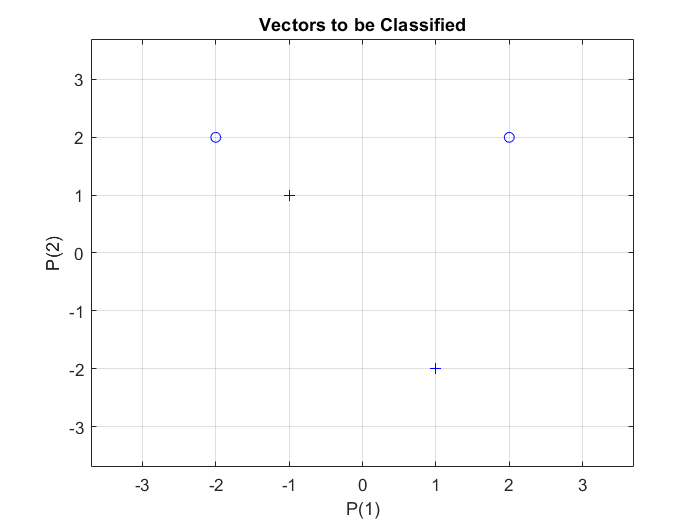

% Cada uno de los cuatro vectores de columna en P define un vectores de entrada de 2 elementos
P = [2 1 -2 -1; 
     2 -2 2 1];
% El vector fila T define las categorías del vector objetivo. 
T = [0 1 0 1];

% Plot input/target vectors
plotpv(P,T);
grid on;

Step 2) PERCEPTRON 

`perceptron` crea una nueva red neuronal con una sola neurona

% con función de activación 'hardlim' y regla de aprendizaje 'learnp'
net = perceptron('hardlim', 'learnp');

% CONFIGURE configura la red con los datos P y T (Normalmente el paso de configuración puede ser omitido ya que se hace automáticamente con ADAPT o TRAIN)
net = configure(net, P, T);

Step 3) Training

Weight(1,:) = net.IW{1};
Bias(1,:) = net.b{1};
Y = []; % valores de salida de la red
E = []; % errores de la red
plotpv(P,T);
grid on;
    
for n=1:length(P)
    
    [net,Y(n),E(n)] = adapt(net,P(:,n),T(:,n));
    Weight(n+1,:) = net.IW{1};
    Bias(n+1,:) = net.b{1};
    
    linehandle = plotpc(net.IW{1},net.b{1});
    set(linehandle, 'Color', 'g', 'LineWidth', 1);
    title('Decision boundary');
    
end

R = [T' Y' E' P' Weight(2:end,:) Bias(2:end)];
TR = array2table(R,'VariableNames',{'Target','output','Error','x1','x2','w1','w2','b'})

TR = 4×8 table
    Target    output    Error    x1    x2    w1    w2    b 
    ______    ______    _____    __    __    __    __    __

      0         1        -1       2     2    -2    -2    -1
      1         1         0       1    -2    -2    -2    -1
      0         0         0      -2     2    -2    -2    -1
      1         0         1      -1     1    -3    -1     0


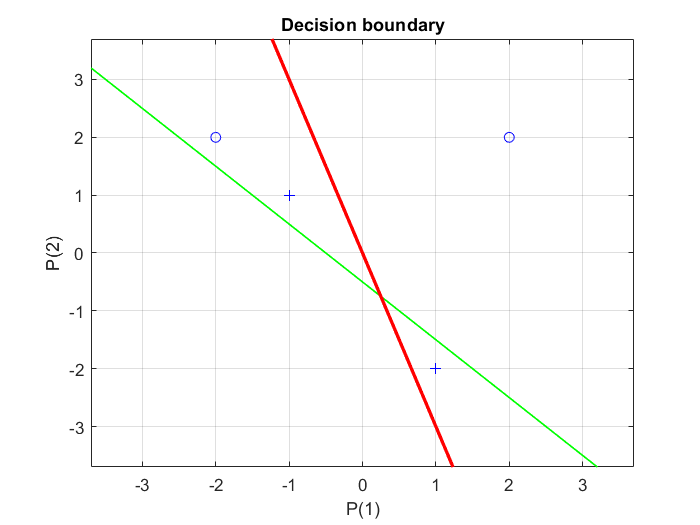

% Límite de decisión final en rojo
linehandle = plotpc(net.IW{1},net.b{1});
set(linehandle, 'Color', 'r', 'LineWidth', 2);
title('Decision boundary');

Step 4) Simulation

Se pide

         1. La función `adapt` (paso 3) actualiza la red para cada ciclo de entrenamiento y devuelve una nueva red que debería clasificar mejor. Utilice el código 0 (CODE 0) para comprobar el correcto incremento de los pesos (ΔW) y el bias (Δb) según: `ΔW=(T−Y)(P)` y` Δb=(T−Y)` respectivamente. ¿Cuándo cambian los pesos? 

         2. Después de ejecutar el punto anterior. ¿Es correcta la frontera de decisión final? ¿Por qué?

         3. Adapte el código 1 (CODE 1) para realizar un entrenamiento que llame a la función `adapt` hasta que la suma del error cuadrático (función `sse`) sea nula o el número de interaciones `n` llegue a 100. ¿se obtiene una fontera de decisión correcta?¿cuántas iteraciones (epoch) han sido necesarias?  

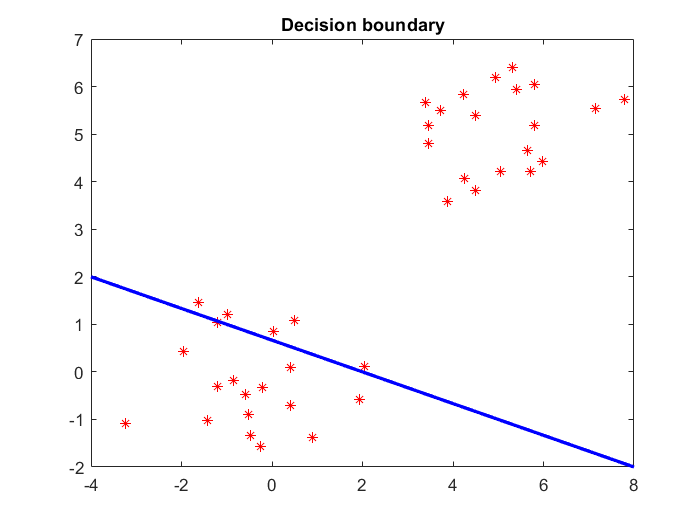

net = configure(net,P,T);

E = 1; % errores de la red
n = 0;

while (sse(E) > 0 && n < 100)    
   n = n + 1;
   [net, Y, E] = adapt(net, P, T);
end

linehandle = plotpc(net.IW{1},net.b{1});
set(linehandle, 'Color', 'b', 'LineWidth', 2);
title('Decision boundary');

         4. Adapte el código 2 para obtener nuevos valores de entrada aleatorios (`P_sim`). Realice la simulación, con la función `sim`, de estos nuevos puntos y compruebe que el perceptrón clasifica correctamente (paso 4).

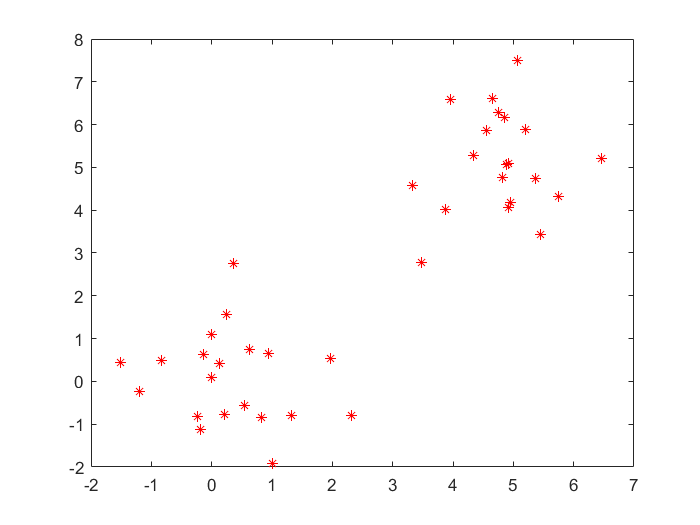

% número de muestras de cada clase
N = 20;

% definir las entradas
offset = 5; % offset para la segunda clase
P_sim = [randn(2,N) randn(2,N) + offset]; % entradas

figure;
plot(P_sim(1,:), P_sim(2,:), 'r*');

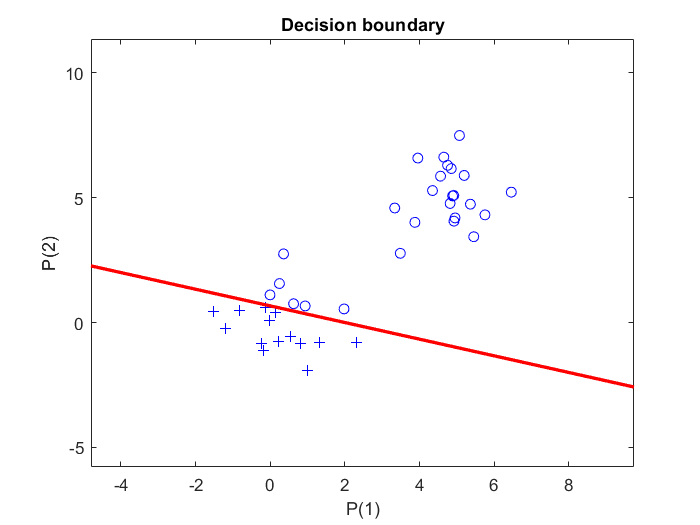

y_sim = sim(net, P_sim);

plotpv(P_sim, y_sim);
linehandle = plotpc(net.IW{1}, net.b{1});
set(linehandle, 'Color', 'r', 'LineWidth', 2);
title('Decision boundary');

         5. Cambie los vectores de entrada (P) y de target (T) por estos valores: `P =[-0.5 -0.5 +0.3 -0.1 -40; -0.5 +0.5 -0.5 +1.0 50]; T =[1 1 0 0 1];`, que tienen una entrada atípica (outlier). Entrene una nueva red y compruebe cuántas iteraciones (épocas) son necesarias antes de obtener una frontera de decisión correcta. 

net = perceptron('hardlim', 'learnp');

P = [-0.5 -0.5 +0.3 -0.1 -40; 
     -0.5 +0.5 -0.5 +1.0 50]; 
T = [1 1 0 0 1];

net = configure(net, P, T);

E = 1; % errores de la red
n = 0; % nº iteraciones

while (sse(E) > 0 && n < 100)    
   n = n + 1;
   [net, Y, E] = adapt(net, P, T);
end

disp(n);

    35



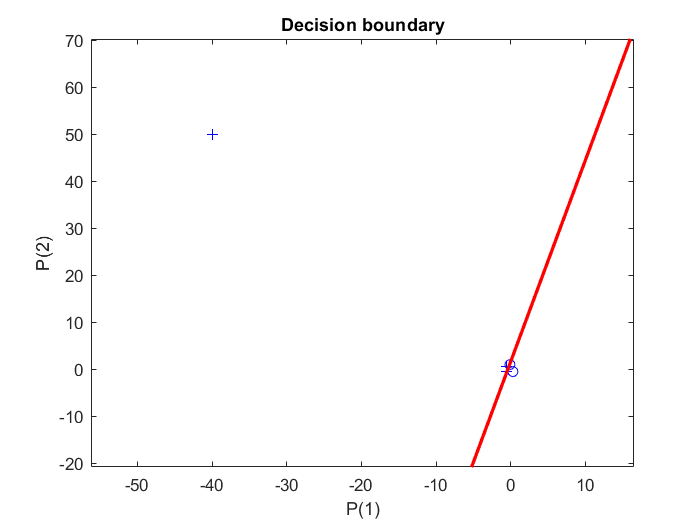

Y = sim(net, P);

figure;
plotpv(P, T);
linehandle = plotpc(net.IW{1}, net.b{1});
set(linehandle, 'Color', 'r', 'LineWidth', 2);
title('Decision boundary');

         6. Para reducir el número de iteraciones cuando hay entradas de valores atípicos, la solución es normalizar. La regla de percepción normalizada se implementa con la función `learnpn`. Cambie `net=perceptron` por `net=perceptron('hardlim','learnpn');` y comprobe si el número de iteraciones ahora es menor.

net = perceptron('hardlim', 'learnpn');

P = [-0.5 -0.5 +0.3 -0.1 -40; 
     -0.5 +0.5 -0.5 +1.0 50]; 
T = [1 1 0 0 1];

net = configure(net, P, T);

E = 1; % errores de la red
n = 0; % nº iteraciones

while (sse(E) > 0 && n < 100)    
   n = n + 1;
   [net, Y, E] = adapt(net, P, T);
end

disp(n)

     4



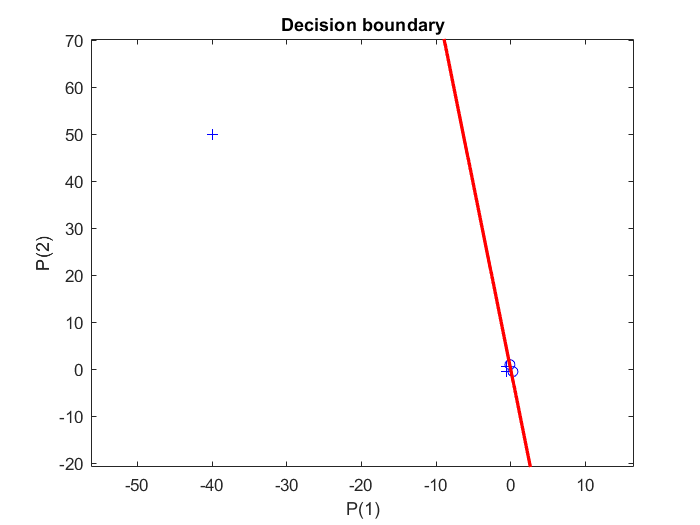

Y = sim(net, P);

figure;
plotpv(P, T);
linehandle = plotpc(net.IW{1}, net.b{1});
set(linehandle, 'Color', 'r', 'LineWidth', 2);
title('Decision boundary');

         7. Finalmente, cambie los vectores de entrada (P) y de target (T) por estos valores: `P =[ -0.5 -0.5 +0.3 -0.1 -0.8; -0.5 +0.5 -0.5 +1.0 +0.0 ]; T =[1 1 0 0 0];`. Entrene una nueva red y compruebe que no se obtiene una frontera de decisión correcta. ¿Por qué la red alcanza el número máximo de iteraciones con un error distinto de cero?

net = perceptron('hardlim', 'learnpn');

P = [-0.5 -0.5 +0.3 -0.1 -0.8;
     -0.5 +0.5 -0.5 +1.0 +0.0]; 
T = [1 1 0 0 0];

net = configure(net, P, T);

E = 1; % errores de la red
n = 0; % nº iteraciones

while (sse(E) > 0 && n < 100)    
   n = n + 1;
   [net, Y, E] = adapt(net, P, T);
end

disp(n)

   100



disp(E)

     0     1     0     0    -1



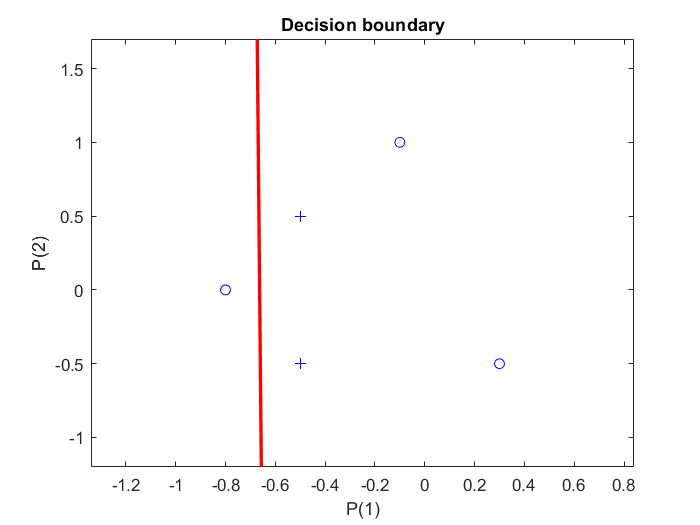

Y = sim(net, P);

figure;
plotpv(P, T);
linehandle = plotpc(net.IW{1}, net.b{1});
set(linehandle, 'Color', 'r', 'LineWidth', 2);
title('Decision boundary');

**Este es un ejemplo de problema no separable linealmente.**

% CODE (0)

R = [T' Y' E' P' Weight(2:end,:) Bias(2:end)];
TR = array2table(R,'VariableNames',{'Target','output','Error','x1','x2','w1','w2','b'})

TR = 4×8 table
    Target    output    Error    x1    x2    w1    w2    b 
    ______    ______    _____    __    __    __    __    __

      0         0         0       2     2    -2    -2    -1
      1         1         0       1    -2    -2    -2    -1
      0         0         0      -2     2    -2    -2    -1
      1         1         0      -1     1    -3    -1     0


% CODE (1)

net = configure(net,P,T);

E = 1; % errores de la red
n=0;
while (sse(E) > 0 & n < 100)    
   n = n + 1;
   [net, Y, E] = adapt(net, P, T);
end

% CODE (2)

% número de muestras de cada clase
N = 20;
% definir las entradas
offset = 5; % offset para la segunda clase
P_sim = [randn(2,N) randn(2,N)+offset]; % entradas

y = sim(net,P_sim);
